% Load historical stock price data
filePath = '/Users/raswanthmalaisamy/Desktop/math stock forecasting/NVDA.csv'; % Ensure the file is in the same directory or provide the full path

% Check if the file exists
if ~isfile(filePath)
    error('File does not exist. Please check the file path.');
end

% Load the data with original column headers preserved
opts = detectImportOptions(filePath);
opts.VariableNamingRule = 'preserve';
data = readtable(filePath, opts);

% Extract adjusted closing prices and dates
dates = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd'); % Convert dates to datetime format
adj_close_prices = data.('Adj Close'); % Access the 'Adj Close' column using the original name

% Preprocess the data
adj_close_prices = fillmissing(adj_close_prices, 'linear'); % Handle missing values with linear interpolation

% Parameters for DMD
window_size = 30; % Size of the sliding window
r = 10; % Truncation rank
forecast_steps = 10; % Number of future steps to forecast

% Construct the data matrix X and X'
X = [];
for i = 1:(length(adj_close_prices) - window_size + 1)
    X = [X, adj_close_prices(i:i + window_size - 1)];
end
X_prime = X(:, 2:end);
X = X(:, 1:end-1);

% Apply DMD
[U, S, V] = svd(X, 'econ'); % Singular Value Decomposition
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);
Atilde = Ur' * X_prime * Vr / Sr; % Reduced-order linear operator

[W, D] = eig(Atilde); % Eigen decomposition
Phi = X_prime * Vr / Sr * W; % DMD modes

% Initial condition for future prediction
x1 = X(:, end);

% DMD eigenvalues and modes
lambda = diag(D);
omega = log(lambda);

% Time dynamics for reconstruction
time_dynamics = zeros(r, size(X, 2));
b = Phi \ x1;
for i = 1:size(X, 2)
    time_dynamics(:, i) = (b .* exp(omega * i));
end

% Reconstruct the data
X_dmd = Phi * time_dynamics;

% Forecast future values
future_dynamics = zeros(r, forecast_steps);
for i = 1:forecast_steps
    future_dynamics(:, i) = (b .* exp(omega * (size(X, 2) + i)));
end
future_prices = real(Phi * future_dynamics);

% Debugging: Print the sizes of matrices
disp(['Size of X_dmd: ', num2str(size(X_dmd))]);

Size of X_dmd: 30  222


disp(['Size of future_prices: ', num2str(size(future_prices))]);

Size of future_prices: 30  10



% Combine historical and forecasted data
forecasted_prices = [real(X_dmd(:, end)); future_prices(:)];

% Debugging: Print the size of forecasted_prices
disp(['Size of forecasted_prices: ', num2str(size(forecasted_prices))]);

Size of forecasted_prices: 330    1



% Determine whether to buy or sell based on the forecasted prices
last_price = adj_close_prices(end);
forecasted_price = forecasted_prices(1); % Taking the first forecasted price for comparison

if forecasted_price > last_price
    action = 'Buy'
elseif forecasted_price < last_price
    action = 'Sell'
else
    action = 'Hold'
end

action = 'Buy'


% Ensure forecast_dates has the same number of elements as forecasted_prices
forecast_dates = dates(end) + caldays(1:forecast_steps);

% Combine historical and forecasted dates
combined_dates = [dates; forecast_dates'];

% Debugging: Print the size of combined_dates
disp(['Size of combined_dates: ', num2str(size(combined_dates))]);

Size of combined_dates: 262    1



% Check lengths of the vectors
disp(['Length of combined_dates: ', num2str(length(combined_dates))]);

Length of combined_dates: 262


disp(['Length of forecasted_prices: ', num2str(length(forecasted_prices))]);

Length of forecasted_prices: 330


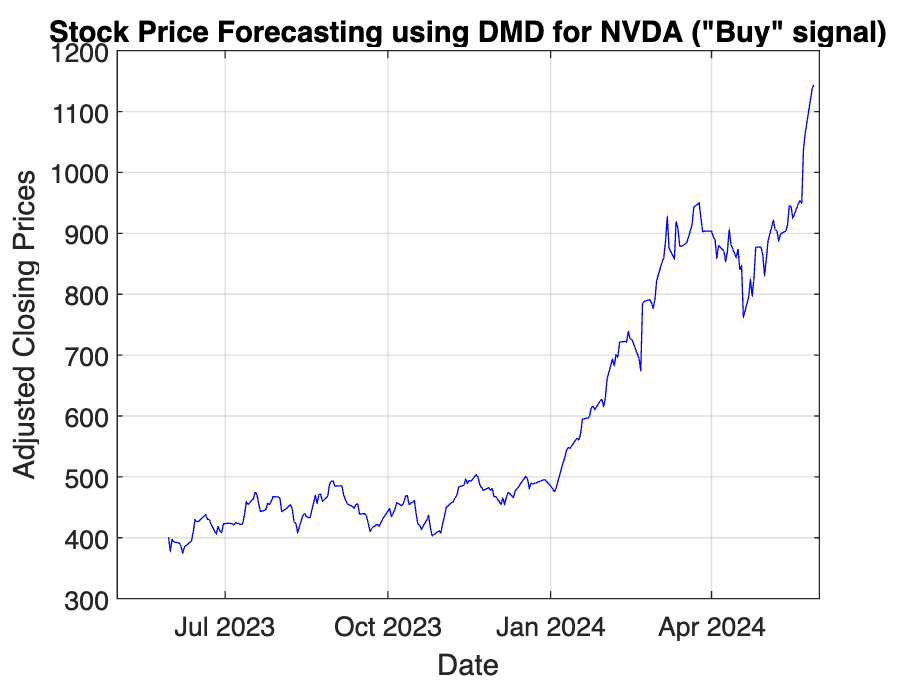


% Adjust the starting index of forecasted_prices to match combined_dates length
plot_start_index = length(dates) - length(forecasted_prices) + 1;
plot_start_index = max(plot_start_index, 1); % Ensure the index is within valid range

% Plot the results
figure;
plot(dates, adj_close_prices, 'b', 'DisplayName', 'Original Data');
hold on;

xlabel('Date');
ylabel('Adjusted Closing Prices');
title(['Stock Price Forecasting using DMD for NVDA ("' action '" signal)']);
grid on;